clc; clear; close all;
data = readtable('Five_times_Kinematics_HT_Query_MATLAB_SIN_OUTLIERS.xlsx');


fprintf('Dimensiones del dataset: %d filas x %d columnas\n', size(data,1), size(data,2));

Dimensiones del dataset: 46 filas x 87 columnas


disp('Variables del dataset:');

Variables del dataset:


disp(data.Properties.VariableNames);

    {'reclutado'}    {'GroupName'}    {'x1_AAFEM'}    {'x2_AAFEM'}    {'x3_AAFEM'}    {'x4_AAFEM'}    {'x5_AAFEM'}    {'x1_AAIEM'}    {'x2_AAIEM'}    {'x3_AAIEM'}    {'x4_AAIEM'}    {'x5_AAIEM'}    {'x1_AKFEM'}    {'x2_AKFEM'}    {'x3_AKFEM'}    {'x4_AKFEM'}    {'x5_AKFEM'}    {'x1_AKAAM'}    {'x2_AKAAM'}    {'x3_AKAAM'}    {'x4_AKAAM'}    {'x5_AKAAM'}    {'x1_AKIEM'}    {'x2_AKIEM'}    {'x3_AKIEM'}    {'x4_AKIEM'}    {'x5_AKIEM'}    {'x1_AHPFEM'}    {'x2_AHPFEM'}    {'x3_AHPFEM'}    {'x4_AHPFEM'}    {'x5_AHPFEM'}    {'x1_AHPAAM'}    {'x2_AHPAAM'}    {'x3_AHPAAM'}    {'x4_AHPAAM'}    {'x5_AHPAAM'}    {'x1_AHPIEM'}    {'x2_AHPIEM'}    {'x3_AHPIEM'}    {'x4_AHPIEM'}    {'x5_AHPIEM'}    {'x1_APTILTM'}    {'x2_APTILTM'}    {'x3_APTILTM'}    {'x4_APTILTM'}    {'x5_APTILTM'}    {'x1_APOBLIM'}    {'x2_APOBLIM'}    {'x3_APOBLIM'}    {'x4_APOBLIM'}    {'x5_APOBLIM'}    {'x1_APROTM'}    {'x2_APROTM'}    {'x3_APROTM'}    {'x4_APROTM'}    {'x5_APROTM'}    {'x1_ASPMLM'}    {'x2_ASPMLM'}    {'x3_ASP

isNum = varfun(@isnumeric, data, 'OutputFormat','uniform');
numericData = data(:, isNum);
X = table2array(numericData);
[n, p] = size(X);
fprintf('El dataset tiene %d muestras y %d dimensiones.\n', n, p);

El dataset tiene 46 muestras y 87 dimensiones.


Eliminamos los outliers detectados anteriormente

% IDs de filas outliers detectadas manualmente
outlierRows = [1, 21, 27,41];

% Eliminar esas filas
X_sin_outliers = X;
X_sin_outliers(outlierRows, :) = [];

% Actualizar número de muestras
n = size(X_sin_outliers, 1);
fprintf('El dataset sin outliers tiene %d muestras y %d dimensiones.\n', n, p);

El dataset sin outliers tiene 42 muestras y 87 dimensiones.


QQ-plot para analizar la normalidad univariada

fprintf('Evaluación de normalidad, QQ-plot SIN outliers:\n');

Evaluación de normalidad, QQ-plot SIN outliers:


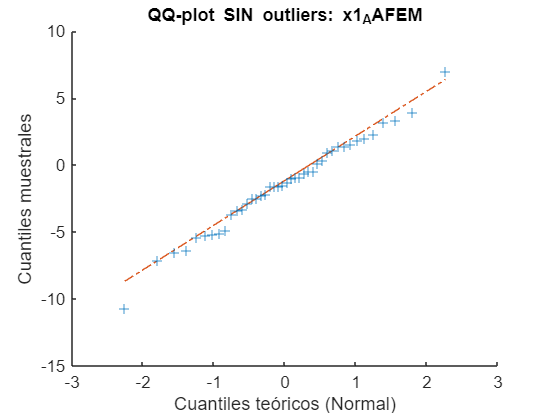

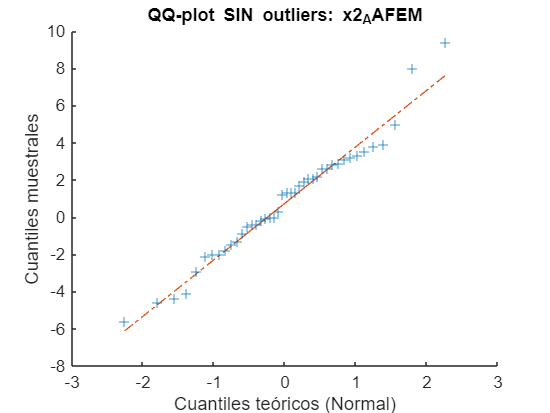

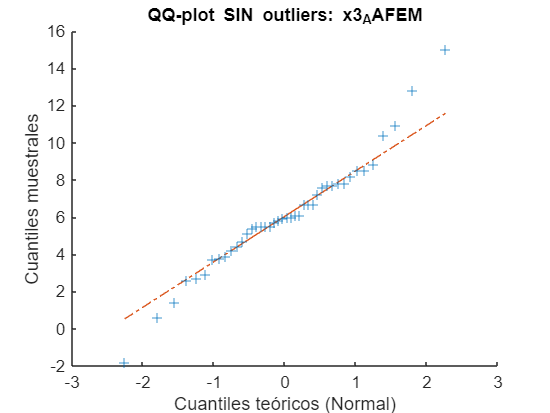

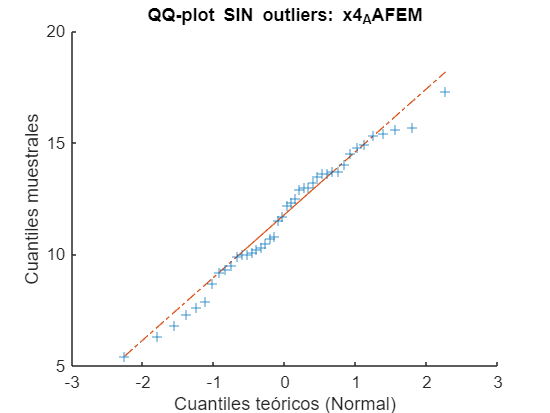

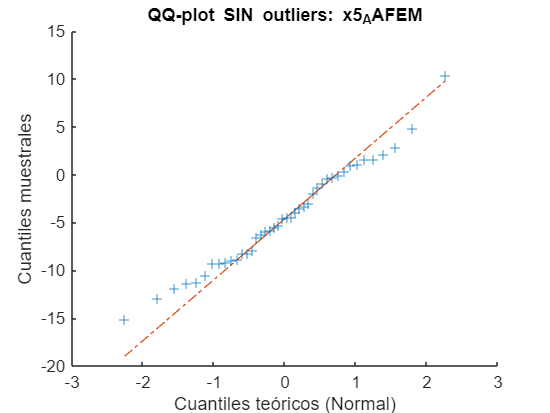

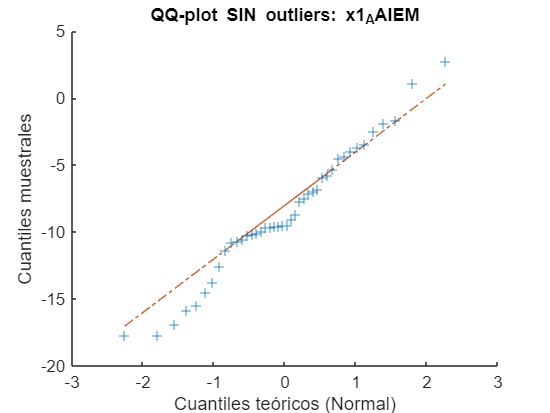

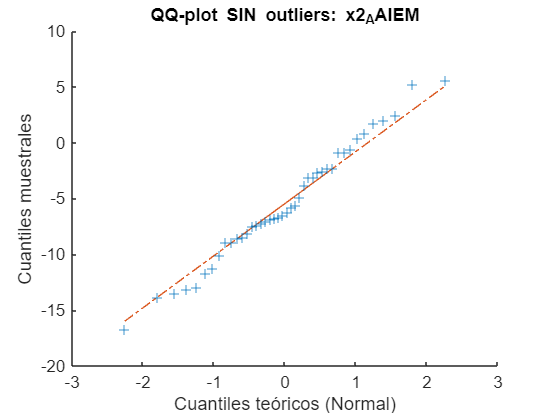

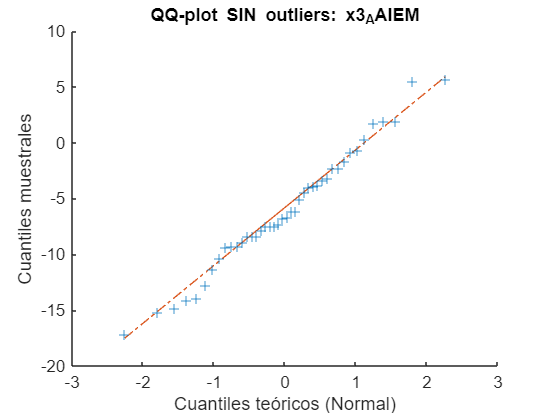

for j = 3:p
    colData = X_sin_outliers(:, j);
    varName = numericData.Properties.VariableNames{j};
    
    % QQ-plot con outliers
    figure;
    qqplot(colData);
    title(['QQ-plot SIN outliers: ', varName]);
    xlabel('Cuantiles teóricos (Normal)');
    ylabel('Cuantiles muestrales');
end